# SIR Notebook 2: Data and Fitting

*Author:* Zachary del Rosario, Fall 2020

*Learning Objectives:* As a result of working through this notebook, you will learn:

- How to read data into Matlab

- How to compare simulations against data

- Some tips for testing model sensitivity

## Fitting a Model with Data

In the previous notebook we made arbitrary choices for $\beta, \gamma$, which is fine for *testing *a model. However, we can't simply make arbitrary choices if we're trying to use a model to describe reality. We need to *fit* our model's parameters $\beta, \gamma$ by studying real data. *Fitting *a model means adjusting its inputs to best-represent a physical scenario. Often we want to do this to make predictions or to support design decisions. Let's consider a specific scenario to make this more concrete:

### Scenario

Let's imagine we're in the middle of cold season: We're living in a fairly small community and we've noticed that a number of folks have come down with the flu. We're in week six of flu season, and we're interested in how much longer it's going to last. 

- The total population is 100 persons.

- At Week 0 *some number* of persons have the flu.

- From tracking sick individuals, we've noticed that people tend to recover from this flu in two weeks.

- It's Week 6, and we've surveyed everyone in the 100-person community; we have a record of how many people were sick in each week.

We're interested in answering the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

- How much confidence do we have in our answers to the questions above?

I provide data for this scenario in `infected.csv`. (*Note:* CSV stands for "comma-separated value"; it's a simple kind of file format.) The following code loads data from this scenario and plots it over time.

% Load the data
tab_data = readtable("infected.csv", "Delimiter", ",")

tab_data = 6×2 table
    W    I 
    _    __

    1     2
    2     3
    3     5
    4     8
    5    11
    6    16


Note that `tab_data` is a Matlab *table: *This is a convenient object for storing data. We'll talk more about tables later in the class: For now I'll just unpack these values into variables so we don't have to deal with tables for now.

% Unpack the table
I_data = tab_data.I;
W_data = tab_data.W;

Now let's plot the data.

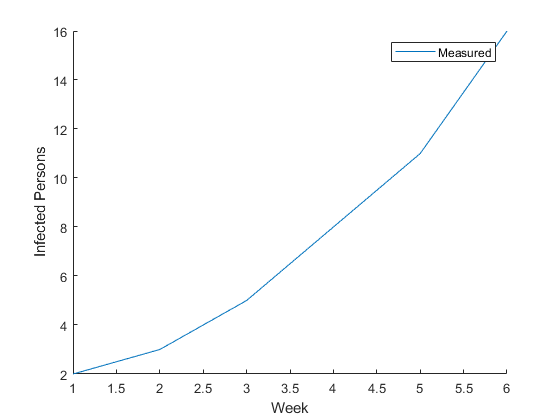

% Plot the data
figure(1); clf; hold on;
plot(W_data, I_data); label1 = "Measured";

xlabel("Week")
ylabel("Infected Persons")
legend({label1})

**Exercise:** Take a look at the values in I`_data`; what do you notice about the values?

*They're monotontically increasing, at a roughly exponential rate.*

## Fitting Parameters

Since we have information about a scenario, we can try to adjust the parameters to match the available data: This process is called *fitting the model*. Let's compare the simulation results from the previous notebook. How well do arbitrary choices for $\beta, \gamma$ and the initial number of infected i_0 match the data?

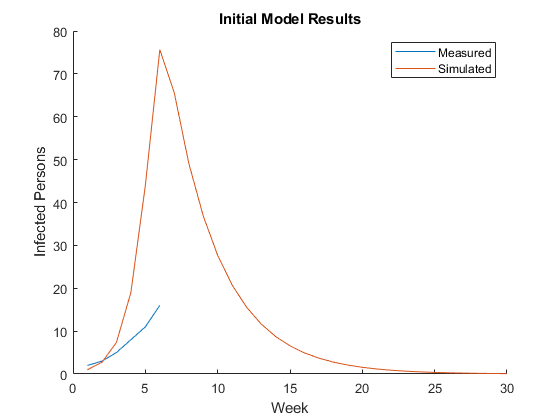

% Define initial state
% A population of 100 persons, 99 susceptible and 1 infectious
s_0 = 99;
i_0 = 1;
r_0 = 0;

% Let's interpret t to be Weeks; thus
% Infection rate: Each infected person has a chance to infect 1 susceptible
%                 person out of 50
% Recovery rate: The infection lasts 4 weeks before recovery
beta = 1 / 50;
gamma = 1 / 4;

% Run simulation
[S_sim, I_sim, R_sim, W_sim] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the data
figure(2); clf; hold on;
plot(W_data, I_data); label1 = "Measured";
plot(W_sim, I_sim); label2 = "Simulated";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Initial Model Results")

**Exercise:** Compare the measured and simulated curves. What is similar about them? What is different? What simulation settings might need tweaking?

*They both seem to start off on a roughly exponential curve, but the measured data has a far less steep curve than the simulated data (and, of course, only goes for the first six weeks).*

Before we go randomly-changing model parameters, we should first get a handle on *model sensitivity*.

### Model sensitivity

All models are *sensitive---*to some degree or another---to their inputs; for instance, our SIR model results change with changes to the parameters $\beta, \gamma$ and starting conditions `s, i, r`. Before we go randomly-changing these values in an attempt to fit data, we should first build a *mental model* for how changing the inputs changes the simulation results. We should build intuition for the model sensitivity.

The following code slightly tweaks the value of $\gamma$, re-runs the simulation, and compares the baseline and tweaked model results.

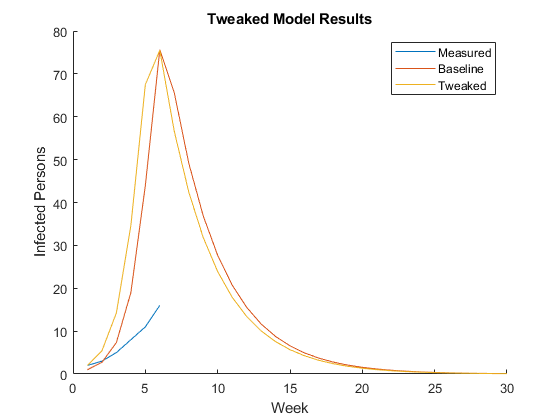

% Define parameters
beta = 1 / 50; % Baseline: beta = 1 / 50
gamma = 1 / 4; % Baseline: gamma = 1 / 4
i_0 = 2;       % Baseline: i_0 = 1

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_twk, I_twk, R_twk, W_twk] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the data
figure(3); clf; hold on;

plot(W_data, I_data); label1 = "Measured";
plot(W_sim, I_sim); label2 = "Baseline";
plot(W_twk, I_twk); label3 = "Tweaked";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2, label3})
title("Tweaked Model Results")

**Exercise:** Systematically adjust the values of $\beta, \gamma$ and `i_0. `Record what each value *physically represents*, and document how changing their values tend to affect model results. Which of $\beta, \gamma$ and `i_0` tends to *most dramatically* change the results? Which tends to *least dramatically* change the results?

- $\beta$ represents the rate at which infected people get other people sick: Increasing $\beta$ tends to shift the curve/spike forward and make the spike steeper.

- $\gamma$ represents the rate at which infected people recover: Increasing $\gamma$ tends to make the spike shorter and more gradual, ending the outbreak sooner.

- `i_0` represents the number of infected people at the beginning of the flu season : Increasing `i_0` tends to simply move an identically-shaped outbreak forward, plus-or-minus some rounding because we only compute on a week-by-week basis.

### Principled Model Fitting

Now that we have some physical understanding of our model inputs $\beta, \gamma$ and `i_0`, we can do some *principled* model fitting. First, we'll use our physical understanding of the inputs to try to set some of them directly. Then we'll use the data to try to set the remaining parameters.

**Direct Setting**: We know from the scenario how many people were infected at Week 0; it's in our dataset!

% Look at week zero
tab_data(tab_data.W == 1, :)

ans = 1×2 table
    W    I
    _    _

    1    2


Thus we can set `i_0 = 2` directly!

Also, we know from data collection some information about the *recovery period*; remember the scenario stated

> "From tracking sick individuals, we've noticed that people tend to recover from this flu in two weeks."

Since $\gamma$ is equal to `1 / recovery_period` (See sir_notebook1`.mlx`), we can set `gamma = 1 / 2`.

**Fitting simulation to data:** The parameter $\beta$ is a bit trickier to set; we can't set it directly based on the information we have. However, we can compare simulation results against data, and use that information to help set $\beta$.

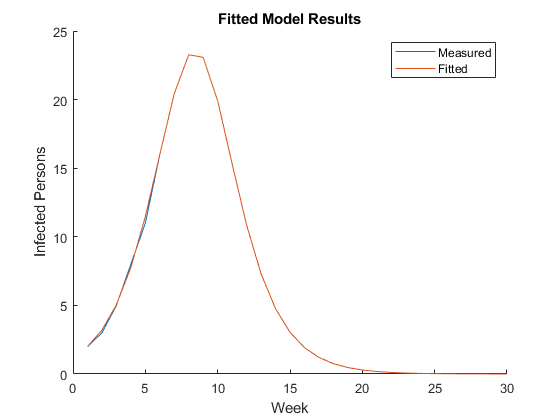

% TODO: Fit this parameter
beta = 1 / 89; % Infection rate (New / Susceptible / Infected / day)

% NOTE: We fit these parameters directly in the steps above
gamma = 1 / 2; % Recovery rate (1 / day)
i_0 = 2;       % Initial count of infected persons

% Define initial state
s_0 = 100 - i_0;
r_0 = 0;

% Run simulation
[S_fit, I_fit, R_fit, W_fit] = sir_simulate(s_0, i_0, r_0, beta, gamma, 30);

% Plot the data
figure(4); clf; hold on;
plot(W_data, I_data); label1 = "Measured";
plot(W_fit, I_fit); label2 = "Fitted";

xlabel("Week")
ylabel("Infected Persons")
legend({label1, label2})
title("Fitted Model Results")

**Exercise: **Manually fit the $\beta$ parameter by comparing the simulation results against data Remember the exercise you did above: Keep in mind how changing $\beta$ tends to change the simulation results. What is the best-fit value for $\beta$ that you found?

*The best value I found for Beta was 89.00, which fits pretty well. 90 fits slightly better for some of the earlier weeks, but it's not a big difference and 89 is spot on for week 6.*

## Using the Model

Congratulations, you just fit your first model! Now that we have a fitted model, we can use it to *make predictions*. Remember that we only have data up through Week 6. We can use the model to make a prediction about future weeks.

**Exercise:** Use your fitted model to plot the over-time trends of `S, I, R` and answer the following questions:

**Questions**

- When will this flu season be over?

- How many of the 100 total persons will fall ill with the flu?

- How much confidence do you have in your answers to these questions?

*Hint:* You can look at `sir_notebook1.mlx` to see a reminder on how to create a plot like this.

% There are some values not explicitly provided that we need to calculate
% to make this graph nice:

S_data = zeros(size(I_data, 1), 1);
R_data = zeros(size(I_data, 1), 1);

S_data(1) = 100 - I_data(1);
R_data(1) = 0;

for idx=2:size(I_data, 1)
    R_data(idx) = I_data(idx - 1) * gamma; % XXX: Not sure this is right
    S_data(idx) = S_data(idx - 1) - (I_data(idx) - I_data(idx - 1) + R_data(idx));
    disp(S_data(idx) + " " + I_data(idx) + " " + R_data(idx))
end

96 3 1
92.5 5 1.5
87 8 2.5
80 11 4
69.5 16 5.5


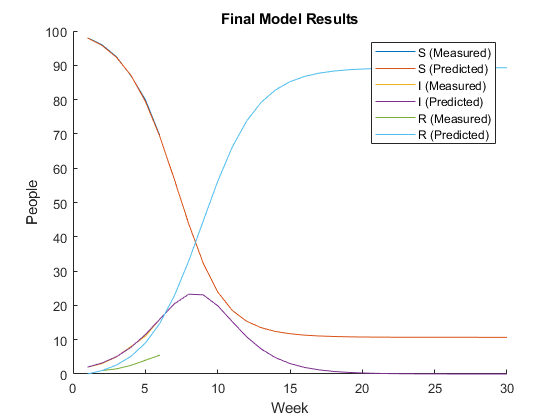


figure(5); clf; hold on;
labels = strings(0);
plot(W_data, S_data); labels(end + 1) = "S (Measured)";
plot(W_fit, S_fit); labels(end + 1) = "S (Predicted)";
plot(W_data, I_data); labels(end + 1) = "I (Measured)";
plot(W_fit, I_fit); labels(end + 1) = "I (Predicted)";
plot(W_data, R_data); labels(end + 1) = "R (Measured)";
plot(W_fit, R_fit); labels(end + 1) = "R (Predicted)";

xlabel("Week")
ylabel("People")
legend(labels)
title("Final Model Results")

## Looking Forward

In the next notebook we'll dig deeper into how we check a model through *validation, *and learn how things can go wrong when we're *missing some physics in our model.*